# Task 2: Perform anomaly detection using incremental learning

In this exercise, we will use the features we extracted before to train a one-class SVM model for anomaly detection. Anomaly detection is the most common embedded AI application for smart appliance. A model is usually trained solely on what believed as normal data and is meant to decide if the any new data represent condition that is not normal. In this example, we treat both inner race fault and outer race fault as anomaly.

## 1. Prepare data that mix normal with anomaly

Create a set of normal data with a small mix of anomaly.

load features.mat
feaTrain = feaTrain([1:5,300:350],:);
rng(0,"twister"); % To reproduce across sessions
feaTrain = feaTrain(randperm(height(feaTrain)),:);

## **2. Incremental Training**

You can train a traditional SVM model if you have relatively balanced data with the fitcsvm function or using the Classification Learner App.

% Mdl = fitcsvm()

In this exercise, we will create an incremental one-class SVM model. The model is updated when new data is available. Fraction of anomalies in the training data is specified as a numeric scalar in the range `[0,1]`.

Mdl = incrementalOneClassSVM("ContaminationFraction",0.1,"ScoreWindowSize",5);
Mdl.ContaminationFraction 

ans = 0.1000

 Fit the model incrementally with normal data accumulate over time. We are going to track some model parameters over time.

% Incremental fitting
rng(0,"twister"); % To reproduce across sessions
n=height(feaTrain);
medianscore = zeros(n,1);
threshold = zeros(n,1);    
numAnom = zeros(n,1);
allscores = [];
for j = 1:n
    Mdl = fit(Mdl,feaTrain{j,2:end});
    [isanom,scores] = isanomaly(Mdl,feaTrain{j,2:end});
    medianscore(j) = median(scores);
    allscores = [allscores scores'];  
    numAnom(j) = sum(isanom);
    threshold(j) = Mdl.ScoreThreshold;
end

At each iteration, the software calculates a score value for each observation in the data chunk. A negative score value with large magnitude indicates a normal observation, and a large positive value indicates an anomaly.

To see how the score threshold and median score per data chunk evolve during training, plot them on separate tiles.

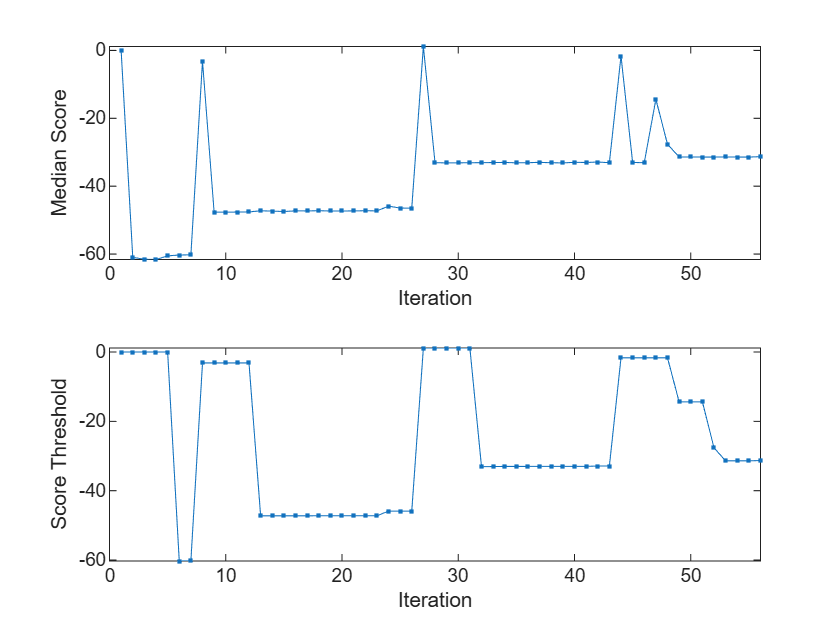

figure
tiledlayout(2,1);
nexttile
plot(medianscore,".-")
ylabel("Median Score")
xlabel("Iteration")
xlim([0 n])
nexttile
plot(threshold,".-")
ylabel("Score Threshold")
xlabel("Iteration")
xlim([0 n])

finalScoreThreshold=Mdl.ScoreThreshold

finalScoreThreshold = -31.3012

## 3. **Model Testing**

So far, we only chose a small amount of data to train this anomaly detection model. Now let's test this model with the testing dataset. We can see, even the model is trained with limited amount of polluted data, the model still performs very well for unseen data. 

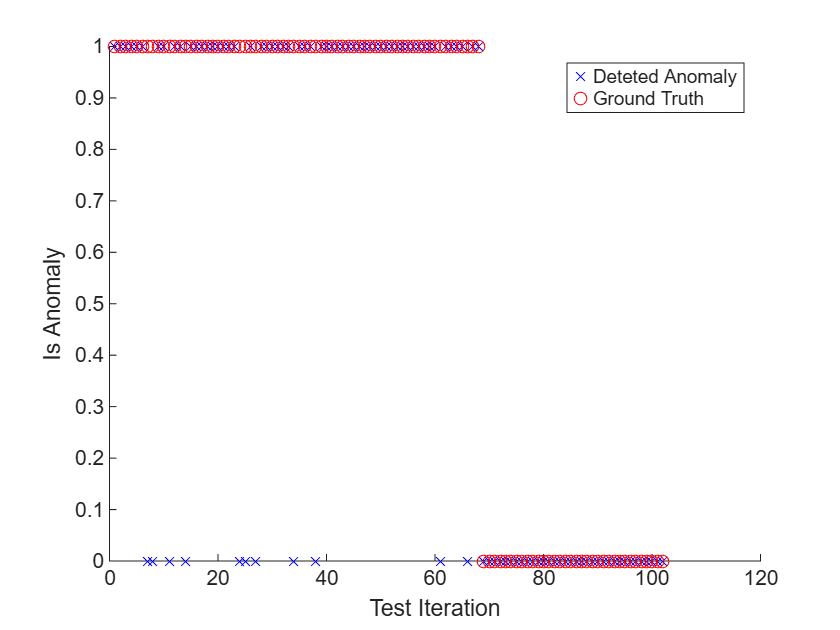

[isanomTest,scoresTest] = isanomaly(Mdl,feaTest{:,2:end});
figure;hold on
plot(1:height(feaTest),isanomTest,'bx');
plot(1:height(feaTest),feaTest{:,1}~="Normal",'ro');
legend("Deteted Anomaly","Ground Truth")
ylabel("Is Anomaly")
xlabel("Test Iteration")